# Project 1: Satellite Attitude Control

AERO 422

*Instructor: Raktim Bhattacharya*

*Aerospace Engineering, Texas*

### Nonlinear Equations of Motion

Consider Euler's first and second law for a general rigid body,


$$\mathbf{F}_\text{total} = m\mathbf{\ddot{X}}}
$$
 


$$\mathbf{M} = \mathbf{I}_\text{cm}\mathbf{\alpha} + \mathbf{\omega}\times(\mathbf{I}_\text{cm}\mathbf{\omega})$$


Let us apply Euler's law to model the dynamics of a satellite. The forces acting on the satellite include external forces such as gravitational forces from the Earth, the Moon, other planets, solar radiation effects, etc. They also include forces exerted by the satellite's control mechanisms such as thrusters and reaction wheels.

We will focus on the attitude, or the orientation, of the spacecraft and thus will only focus on Euler's second law. 

#### Assumptions

- We will assume we can independently exert moments on the satellite, without worrying too much about the exact physical actuation mechanims. Therefore $\mathbf{M}$ is our control variable, which is a vector of three elements. 

- We also assume our initial attitude, defined by three Euler angles $\phi,\theta,\psi$, is such that these angles are all zero.

- We will assume the spacecraft in this attitude also has zero angular velocity, so all three elements of $\mathbf{\omega}$are zero.

- Finally, we will assume the satellite is a symmetric rigid body and our body-fixed coordinate system is based on the axes of symmetry.

### Linear Model

It is easy to show that the **linear **dynamics about this configuration simplifies to three decoupled double integrators, one for each rotational angle, resulting in the following linear equations of motion,


$$\ddot{\phi} = \frac{1}{I_{xx}}M_x,\; \ddot{\theta} = \frac{1}{I_{xx}}M_y, \;\ddot{\psi} = \frac{1}{I_{xx}}M_z. $$


Applying Laplace transform to these three equations will result in the following transfer functions


$$\Phi(s) = \frac{A_x}{s^2}U_x(s),\; \Theta(s) = \frac{A_y}{s^2}U_y(s), \text{ and } \Psi(s) = \frac{A_z}{s^2}U_z(s),
$$


where $A_x := \frac{1}{I_{xx}}, \; A_y := \frac{1}{I_{yy}}, \text{ and } A_z := \frac{1}{I_{zz}}, $and the Laplace transforms of the inputs are defined as$U_x(s) := \mathcal{L}(M_x(t)), \; U_y(s) := \mathcal{L}(M_y(t)), \text{ and } U_z(s) := \mathcal{L}(M_z(t)).$

### Control Design Problem

We want to control design a controller to track a given reference, motivated the need to orient the spacecraft in a certain direction -- for example towards the sun as the spacecraft rotates about the Earth. 

To achieve this goal, we will design **3** **separate** **controllers** to control $\phi(t), \theta(t), \text{ and } \psi(t)$ independently, since we have only learn SISO control system design in AERO 422. Therefore, we will have three SISO controllers in the attitude control system.

We also have to be mindful that the reference angles are not too large to violate the assumptions made in the linearization of the nonlinear spacecraft dynamics.

For simplicity, we will assume $I_{xx}, I_{yy}, \text{ and } I_{zz}
$ to be unity. Therefore, the plant model is given by $\frac{1}{s^2}$, which is also known as a **double integrator. **Since in this case all three systems are identical, we need to only design **one** controller, and use three copies of it to track $\phi(t), \theta(t), \text{ and } \psi(t)$.

s = tf('s');
P = 1/s^2; % Define the open-loop plant.

### **Answer the following questions:**

Q1. Show that the proportional controller does not improve the damping in the system. You will use rlocus to answer the question.

disp("Q1 Proportional controller - damping")

Q1 Proportional controller - damping


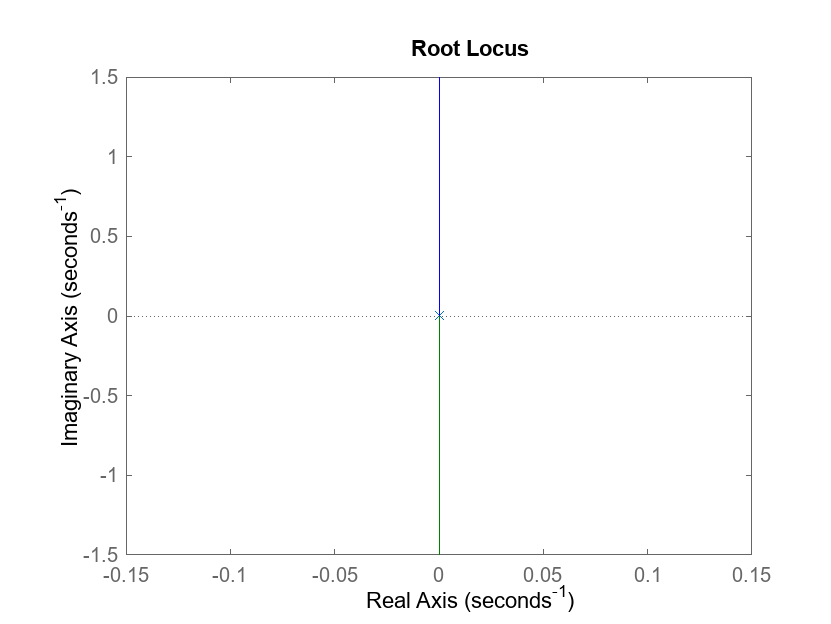

L= P;
figure(1); clf; hold on;
rlocus(L)

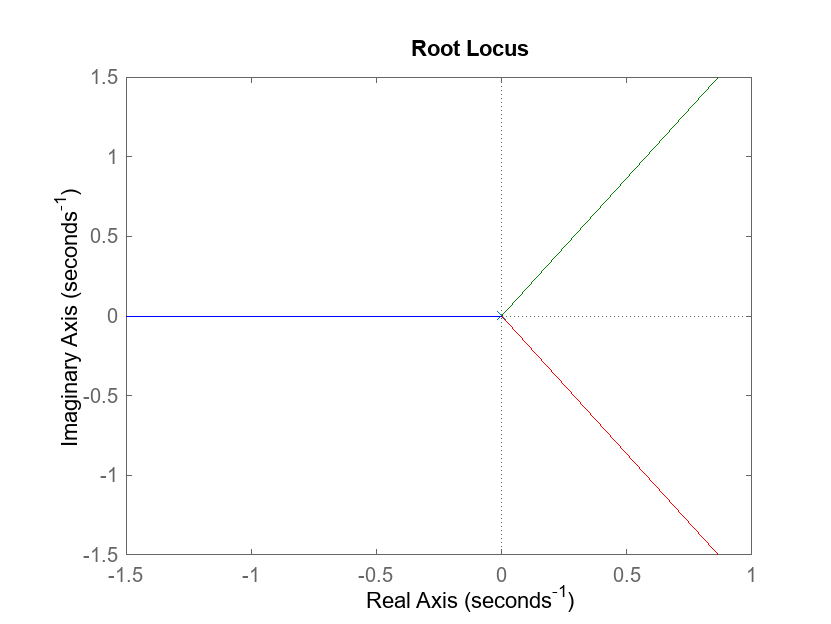


% Just Integral
L = 1/s^3;
figure(2);
rlocus(L)


disp("Because the graph is a straight line the proportional controller does not improve the damping of the system because it is constant.");

Because the graph is a straight line the proportional controller does not improve the damping of the system because it is constant.


Q2. Show that a PI controller destabilizes the system, for any non zero gain on the integral control.  You will use rlocus to answer the question.

disp("Q2 PI controller - destabilizes")

Q2 PI controller - destabilizes


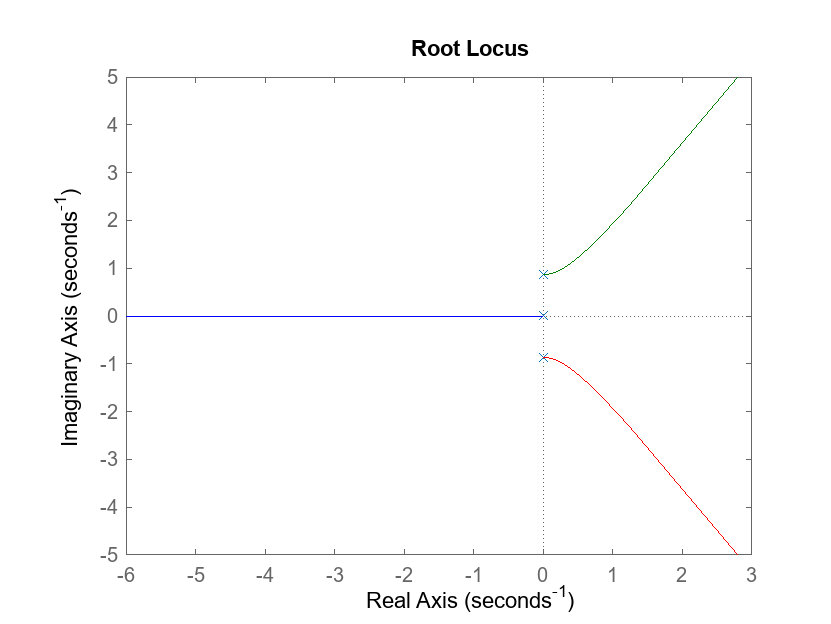

Kp = 0.75;
L = 1/s/(s^2+Kp);
figure(3)
rlocus(L)


disp("A PI controller destabalizes the system this is proven because the graph is pushed to the right side (positive real).");

A PI controller destabalizes the system this is proven because the graph is pushed to the right side (positive real).


Q3. Show that a PD controller is able to obtain the** rise time of 0.5 seconds** and a **settling time of 3 seconds**. 

You will use rlocus to determine the gains, and step(..) to plot the response. We should be able clearly see rise time and settling time. Try to achieve a design with the minimum overshoot.

disp("Q3 PD Controller - rise/settling times")

Q3 PD Controller - rise/settling times


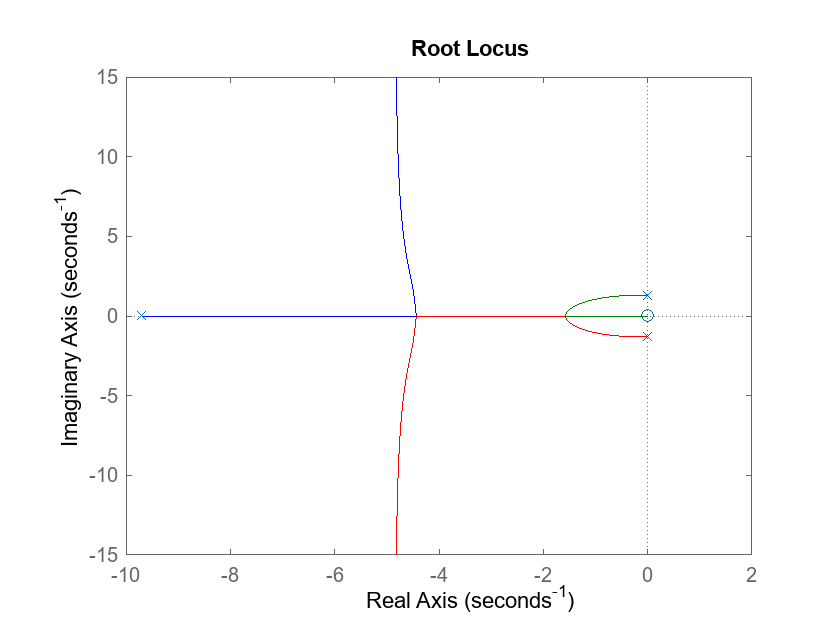

alp = 9.7;
Kp = 1.67;
L = s/(s/alp+1)/(s^2+Kp);
figure(4); 
rlocus(L);

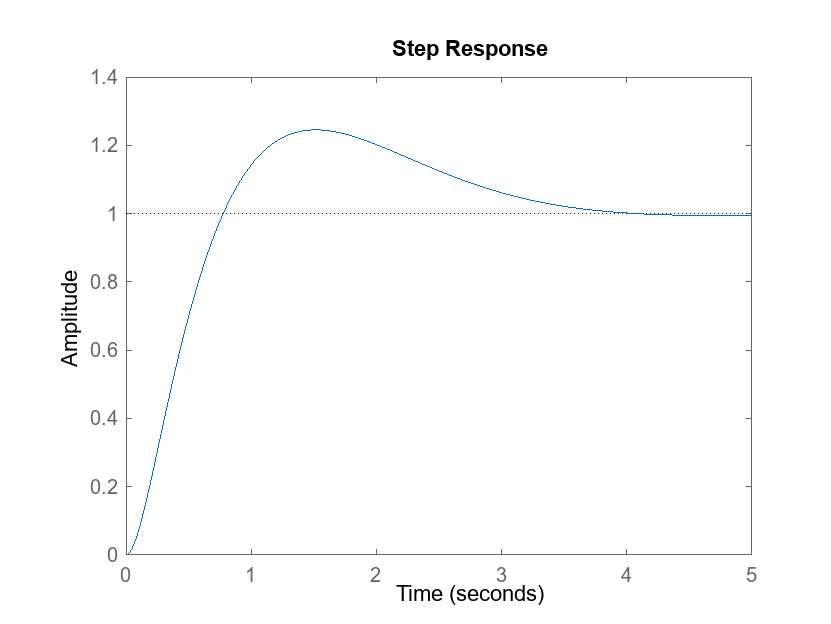


Kd = 1.78;
C = Kp + Kd*s / (s/alp+1);
Gyr = minreal(P*C/(1+P*C));
figure(5);
step(Gyr)


disp('rise time = 0.546');

rise time = 0.546


disp('settling time = 3.52');

settling time = 3.52


disp("")

Q4. Why is it that there is an overshoot in the step response, even when all the closed-loop system poles are real negative with a PD controller? Hint: how does a zero impact the time response of a system.


disp("Q4")

Q4


disp("The total reponse of a system is comprised of a natural response and a forced response. The natural response goes to zero while the forced response oscillates.")

The total reponse of a system is comprised of a natural response and a forced response. The natural response goes to zero while the forced response oscillates.


disp("Meaning, a system can be stable and have some oscillation. Overall, if your system is stable (negative real parts) you can still have overshoot (which is decaying oscillation).")

Meaning, a system can be stable and have some oscillation. Overall, if your system is stable (negative real parts) you can still have overshoot (which is decaying oscillation).


Q5. Use a lead compensator to achieve the rise time and settling time goals. Try to achieve a design with the minimum overshoot.

disp("")
disp("Q5 Lead compensator - rise/settling times")

Q5 Lead compensator - rise/settling times


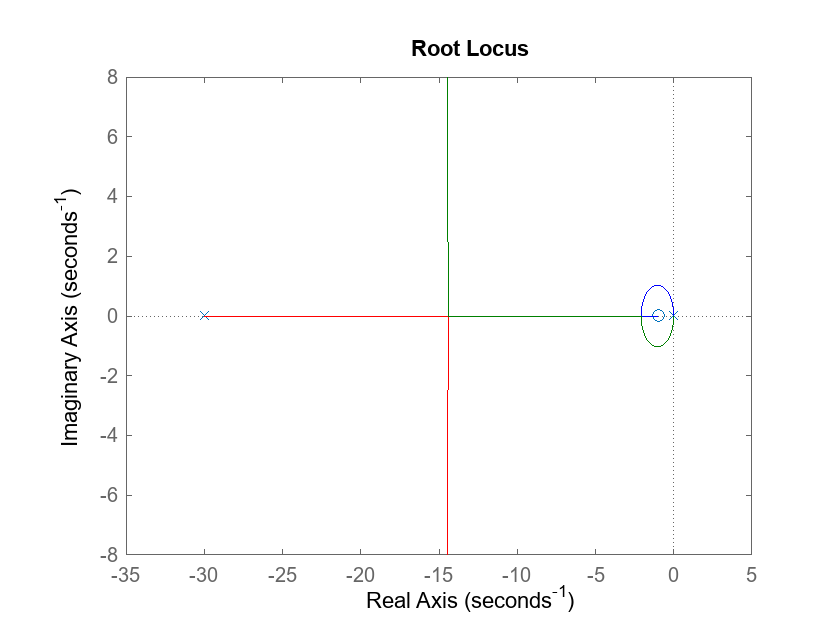


z0 = 1;
p0 = 30;
L = P*(s/z0+1)/(s/p0+1);
figure(4); clf;
rlocus(L)

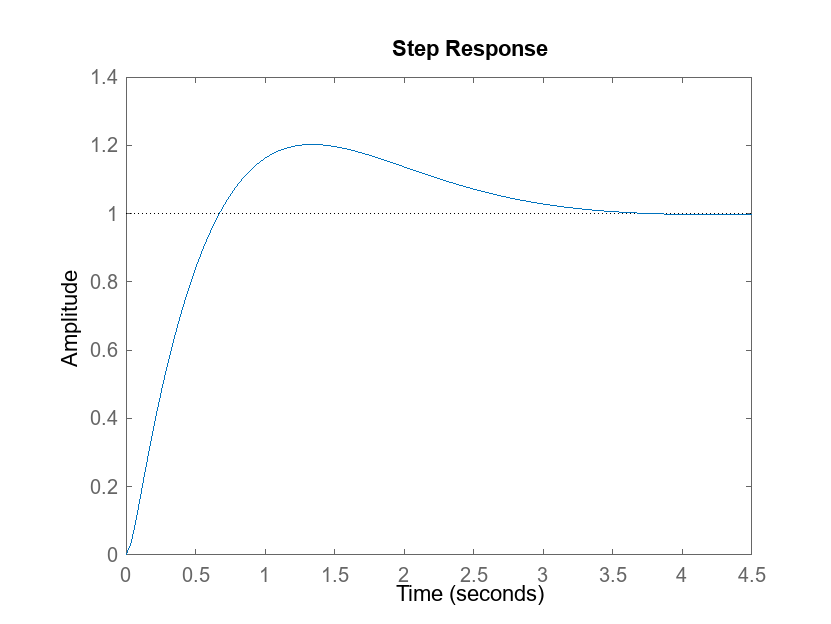


KL = 2.4;
C = KL*(s/z0+1)/(s/p0+1);
Gyr = minreal(P*C/(1+P*C));

figure(5); clf;
step(Gyr);


disp('rise time = 0.486');

rise time = 0.486


disp('settling time = 3.14');

settling time = 3.14
